# FREQUENCY MODULATION

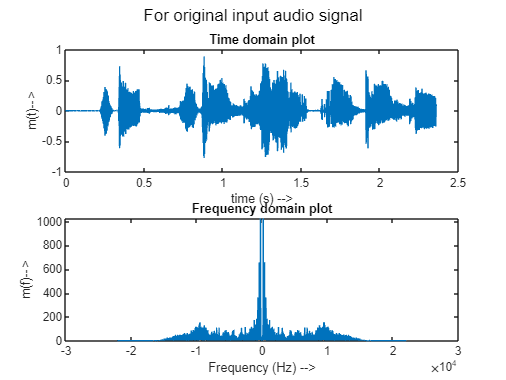


[m, fs] = audioread("little-mix-wasabi.wav"); %This signal has two channels
m = m(:,1); %Taking any one channel
x = fftshift(fft(m));
y = abs(x);

T = 2;
n = length(m);
t = (0:1/fs:(n-1)/fs);
f = (-n/2: n/2 - 1)*(fs/n);

figure(1)
subplot(2,1,1)
plot(t, m);
title('Time domain plot')
xlabel('time (s) -->')
ylabel('m(t)-->')

subplot(2,1,2)
plot(f, y); %fm = 15kHz
title('Frequency domain plot')
xlabel('Frequency (Hz) -->')
ylabel('m(f)-->')

sgtitle('For original input audio signal')

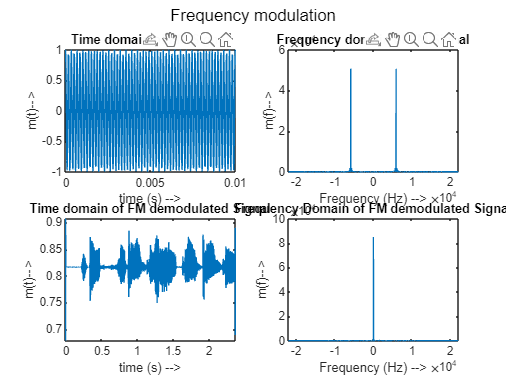

Ac=1;
d = 1/fs;
fc = 50000;
kf = 5000;
%theta = transpose(d*cumsum(m));
theta = transpose(cumtrapz(t,m));
fm = Ac*cos(2*pi*fc*t + kf*theta);

figure(2)
subplot(2,2,1)
plot(t(1:1000),fm(1:1000));
title("Time domain of FM Signal");
xlim([0 0.01])
xlabel('time (s) -->')
ylabel('m(t)-->')

y1 = abs(fftshift(fft(fm)));
subplot(2,2,2)
plot(f, y1)
title("Frequency domain of FM Signal");
xlabel('Frequency (Hz) -->')
ylabel('m(f)-->')

y2 = diff(fm);
y2 = abs(hilbert(y2));
y2 = lowpass(y2,10000,fs);

subplot(2,2,3)
plot(t(1:n-1), y2);
title("Time domain of FM demodulated Signal");
xlabel('time (s) -->')
ylabel('m(t)-->')

y3 = abs(fftshift(fft(y2)));
subplot(2,2,4)
plot(f(1:n-1),y3);
title("Frequency Domain of FM demodulated Signal");
xlabel('Frequency (Hz) -->')
ylabel('m(f)-->')

sgtitle('Frequency modulation')

soundsc(y2, fs)

# PHASE MODULATION

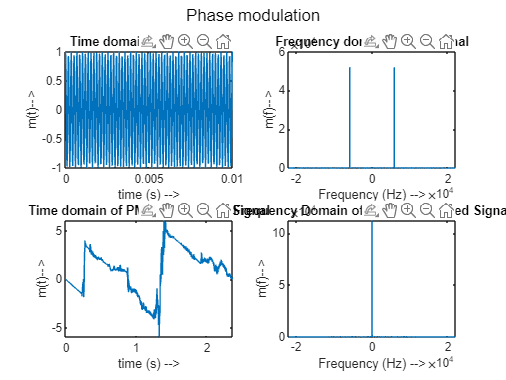

kp = 0.5;
m = transpose(m);
pm = Ac*cos(2*pi*fc*t + kp*m);

figure(3)
subplot(2,2,1)
plot(t(1:1000),pm(1:1000));
xlim([0 0.01])
title("Time domain of PM Signal");
xlabel('time (s) -->')
ylabel('m(t)-->')

y4 = abs(fftshift(fft(pm)));
subplot(2,2,2)
plot(f, y4)
title("Frequency domain of PM Signal");
xlabel('Frequency (Hz) -->')
ylabel('m(f)-->')

y5 = diff(pm)/d;
y5 = abs(hilbert(y5));
y5 = lowpass(y5,10000,fs);
y5 = y5 - mean(y5);
y5 = d*cumsum(y5);

subplot(2,2,3)
plot(t(1:n-1), y5);
title("Time domain of PM demodulated Signal");
xlabel('time (s) -->')
ylabel('m(t)-->')

y6 = abs(fftshift(fft(y5)));
subplot(2,2,4)
plot(f(1:n-1),y6);
title("Frequency Domain of PM demodulated Signal");
xlabel('Frequency (Hz) -->')
ylabel('m(f)-->')

sgtitle('Phase modulation')

soundsc(y5, fs)